# Tutorial of the Unbiased Competition Model

This tutorial demonstrates how to implement the unbiased competition model used in [Ardid, Sherfey et al. 2019](https://doi.org/10.1073/pnas.1812535116).

- **Goals**: 

- llustrate the creation and usage of DynaSim models endowed with mechanisms specified by the user. 

- Show how to modify the dynamics of a model, the Unbiased Competition model in this case, by tuning its internal parameters.

- **Structure**: After a brief introduction, the first sections in the tutorial show how to load `DynaSim` and set up the model. The execution of the model is done in section Run the simulation.  Visualization of the results is explained in section Visualize the results.

- **Reference:**

- "Ardid, Sherfey, McCarthy, Hass, Pittman-Polletta, & Kopell (2019). Biased competition in the absence of input bias revealed through corticostriatal computation", published in Proceedings of the National Academy of Sciences, USA.

## Background

We conceptualize Unbiased Competition as biased competition in the absence of input bias, in contraposition to the traditional Biased Competition conception, which refers to biased competition due to an input bias.

## Load DynaSim

If you haven't loaded DynaSim, do it.

dynasim_path = '../../..';
addpath(genpath(dynasim_path));

## Implementation

In this section we specify the initial settings both of the simulation (how and for how long we integrate the model) and that of the model itself (all its mechanisms and their parameters).

### Simulation parameters

In this section we specify the integration parameters: the integration time step (dt), the solver that we will be using (e.g., rk4), the duration of the simulation, an initial onset time (different than 0 if wanted), and the transient time (which is used to ensure that dynamics is not affected by the initial conditions).

%% Simulation time definition

dt = 0.0500

dt = 0.05           % Integration time step

solver = 'rk4'

solver =  'rk4'      % Integration solver

duration = 1000

duration = 1000     % Simulation duration
tOn = 0;                           % Initial time onset
tspan = [tOn,tOn+duration];        % Simulation interval

transient = 250

transient = 250    % Transient time

### Model specification

We start defining the ordinary differential equations (ODEs) we want to simulate. Later on, we will embed these equations into the model specification (s), which we define in Section Define populations and connections. In this case we integrate each cell's voltage (state variable V) according to its input currents. For this, we use a DynaSim linker (@current) that will be internally replaced by all the input terms. We also need to define the initial conditions of the state variable (V), i.e., its initial value. Finally, we use a DynaSim monitor to tell DynaSim to save the data of the total current (@current) at each time step. 

eqns = {
         'dV/dt = @current'             % Ordinary Differential Equation (ODE)
         'V(0) = -70+10*randn(1,Npop)'   % Initial Conditions (IC)
         'monitor @current'             % Monitor of the total current through the @current Linker
       }

eqns = 3×1 cell array
    {'dV/dt = @current'           }
    {'V(0) = -70+10*randn(1,Npop)'}
    {'monitor @current'           }


### Cell multiplicity

Our model consists of two types of striatal cells: D1 and D2 Spiny Projecting Neurons, D1 and D2 SPNs for short.

nSPNs = 150;     % Number of individual SPN cells

multiplicity =    150   150


multiplicity = [nSPNs,nSPNs]     % Total number of SPN cells of each type [D1 SNPs, D2 SPNs] in the model


### Parameters of intrinsic currents

Section Define populations and connections specifies the list of mechanisms each cell type possesses. These mechanisms are fully specified in separate files. Dynasim users can access a repertoire of mechanisms in DynaSim's Library, but sometimes we need to create our own. In such a case, the path to the mechanisms needs to be 'visible', either because is local to the live script (same folder), or because the mechanisms folders have been previously added to the path. Most of the parameters of the mechanisms have been set in their respective files (we encourage the reader to open and inspect those files). Here we will override only those parameters that take different values in D1 and D2 SPNs.

% Leak current parameters

g_l_D1 = 0.0960

g_l_D1 = 0.096      % mS/cm^2, Leak conductance for D1 SPNs 

g_l_D2 = 0.1000

g_l_D2 = 0.1        % mS/cm^2, Leak conductance for D2 SPNs

% Ca current parameters

g_cat_D1 = 0.0180

g_cat_D1 = 0.018    % mS/cm^2, Conductance of the T-type Ca2+ current for D1 SPNs

g_cat_D2 = 0.0250

g_cat_D2 = 0.025    % mS/cm^2, Conductance of the T-type Ca2+ current for D2 SPNs

### Parameters of external Poisson synaptic inputs from PFC

Here, we override the values of the external Poisson inputs from PFC. We start specifying the interval in which these inputs are applied. Next, we set up the rate of the non-oscillatory component, and consider 3 different conditions: input of high strength, input of low strength, and no input (spontaneous activity). First, we consider non-oscillatory inputs only.

% Interval of the PFC input

tOn_pfcInp = 250

tOn_pfcInp = transient            % onset in ms

tOff_pfcInp = 1000

tOff_pfcInp = tOn+duration        % offset in ms

% Rate of reference for the non-oscillatory (DC) component, i.e. asynchronous input

DC_ref = 44000

DC_ref = 44e3                     % in spks/s

% Three cases: High strength async input, Low strength async input and no input (spontaneous activity)

pfcInp_DC = 44000

pfcInp_DC = DC_ref                % high input

pfcInp_DCred = 8800

pfcInp_DCred = DC_ref/5           % low input

pfcInp_spont = 0

pfcInp_spont = 0                  % no input

### Parameters of recurrent synaptic connections

Similarly, we override parameters of the recurrent GABA connections among SPNs that are specific of each type of connection: the probability of connection, the maximum conductance, the synaptic time constants, as well as the time constant of short-term depression.

% Connection probabilities

conn_prob_gaba_D1toD1 = 0.2600

conn_prob_gaba_D1toD1 = 0.26               % D1->D1 prob. of connection

conn_prob_gaba_D1toD2 = 0.0600

conn_prob_gaba_D1toD2 = 0.06               % D1->D2 prob. of connection

conn_prob_gaba_D2toD1 = 0.2700

conn_prob_gaba_D2toD1 = 0.27               % D2->D1 prob. of connection

conn_prob_gaba_D2toD2 = 0.3600

conn_prob_gaba_D2toD2 = 0.36               % D2->D2 prob. of connection

% GABA maximum conductances

g_gaba_D1 = 0.0043

g_gaba_D1 = 0.65/multiplicity(1)           % mS/cm^2, maximum conductance per cell

g_gaba_D2 = 0.0028

g_gaba_D2 = 0.4125/multiplicity(2)         % mS/cm^2, maximum conductance per cell

cross_inhibition_factor = 1.5000

cross_inhibition_factor = 1.5              % multiplicative factor for cross-inhibition connections (D1->D2 and D2->D1)

% GABA time constant for each connection
median_tau_gaba = 30.4;                    % ms
sig_tau_gaba = 8.2;                        % ms
tau_gaba_D1 = median_tau_gaba + sig_tau_gaba*randn(1,multiplicity(1));
tau_gaba_D2 = median_tau_gaba + sig_tau_gaba*randn(1,multiplicity(2));

% Time constant of short-term depression
tauD_D1 = 1030;                     % ms
tauD_D2 = 210;                      % ms

### Population specification

Here we specify the details of the two populations in the model, D1 and D2 SPNs: number of neurons, main equations, list of mechanisms embedded in each neuron's model and parameters that should be overriden from default values:

s = []; % Create an empty structure to write DynaSim's model full specification

% D1 SPN population specification
s.populations(1).name = 'D1_SPN';
s.populations(1).size = multiplicity(1);
s.populations(1).equations = eqns;
s.populations(1).mechanism_list = {'spn_iNa','spn_iK','spn_iLeak','spn_iM','spn_iCa','spn_CaBuffer','spn_iKca','spn_iPoisson','spn_ipfcPoisson'};
s.populations(1).parameters = {'cm',1,'g_l',g_l_D1,'g_cat',g_cat_D1,'onset_pfc_poisson',tOn_pfcInp,'offset_pfc_poisson',tOff_pfcInp};

% D2 SPN population specification
s.populations(2).name = 'D2_SPN';
s.populations(2).size = multiplicity(2);
s.populations(2).equations = eqns;
s.populations(2).mechanism_list = {'spn_iNa','spn_iK','spn_iLeak','spn_iM','spn_iCa','spn_CaBuffer','spn_iKca','spn_iPoisson','spn_ipfcPoisson'};
s.populations(2).parameters = {'cm',1,'g_l',g_l_D2,'g_cat',g_cat_D2,'onset_pfc_poisson',tOn_pfcInp,'offset_pfc_poisson',tOff_pfcInp};

### Connections specification

Next, we move into the recurrent synaptic connections among the populations and specify their properties: the specific synaptic mechanism utilized, and how its internal parameters are tweaked according to each type of connection: connection probability, maximum conductance and time constants (synaptic and short-time depression):

% D1->D1 connection specification
s.connections(1).direction = 'D1_SPN->D1_SPN';
s.connections(1).mechanism_list = {'spn_iGABA'};
s.connections(1).parameters = {'conn_prob_gaba',conn_prob_gaba_D1toD1,'g_gaba',g_gaba_D1,'tau_gaba',tau_gaba_D1,'tauD_gaba',tauD_D1};

% D1->D2 connection specification
s.connections(2).direction = 'D1_SPN->D2_SPN';
s.connections(2).mechanism_list = {'spn_iGABA'};
s.connections(2).parameters = {'conn_prob_gaba',conn_prob_gaba_D1toD2,'g_gaba',cross_inhibition_factor*g_gaba_D1,'tau_gaba',tau_gaba_D1,'tauD_gaba',tauD_D1};

% D2->D1 connection specification
s.connections(3).direction = 'D2_SPN->D1_SPN';
s.connections(3).mechanism_list = {'spn_iGABA'};
s.connections(3).parameters = {'conn_prob_gaba',conn_prob_gaba_D2toD1,'g_gaba',cross_inhibition_factor*g_gaba_D2,'tau_gaba',tau_gaba_D2,'tauD_gaba',tauD_D2};

% D2->D2 connection specification
s.connections(4).direction = 'D2_SPN->D2_SPN';
s.connections(4).mechanism_list = {'spn_iGABA'};
s.connections(4).parameters = {'conn_prob_gaba',conn_prob_gaba_D2toD2,'g_gaba',g_gaba_D2,'tau_gaba',tau_gaba_D2,'tauD_gaba',tauD_D2};

## Run the simulation

Once the model is properly specified, we proceed to run the simulation according to the simulation parameters and model specification. For this we use the 'vary' argument in DynaSim, so we can run 3 related simulations in 1 call. Specfically, we vary the strength of the asynchronous input coming from PFC, as explained above.

% Simulate pfc DC input variation
pfcInp_DCcond = [pfcInp_spont, pfcInp_DCred, pfcInp_DC];
pfcInp_DCcond_labels = {'Spontaneous', 'Low Async Input', 'High Async Input'};
vary_DC = {
            '(D1_SPN,D2_SPN)','DC_pfc_poisson',pfcInp_DCcond
          };
data = dsSimulate(s,'time_limits',tspan,'vary',vary_DC,'dt',dt,'solver',solver);

## Visualize the results

Finally, we display the raster plots of the two populations (D1 SPNs in blue, and D2 SPNs in red), as well as individual voltage traces from those simulations as follows:

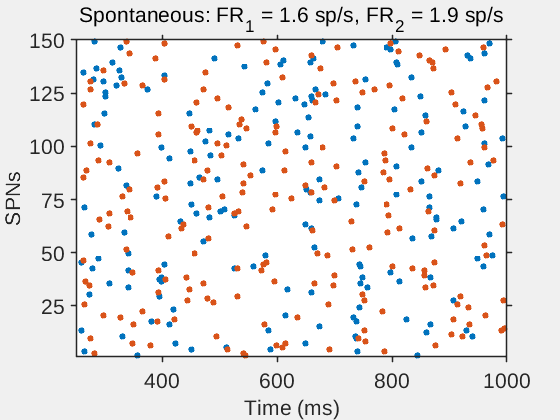

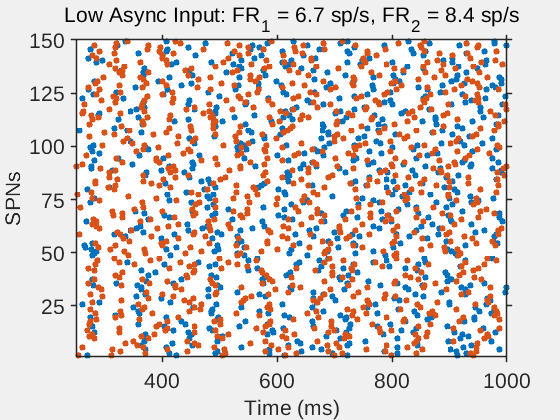

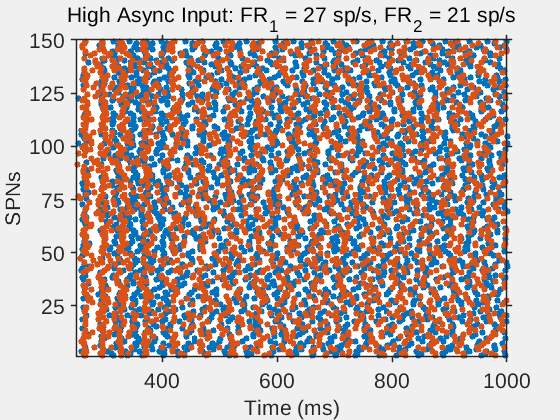

% Raster plots (Fig. 3A)
for iSim = 1:numel(pfcInp_DCcond)
    raster{1} = computeRaster(data(iSim).time,data(iSim).D1_SPN_V);
    raster{2} = computeRaster(data(iSim).time,data(iSim).D2_SPN_V);
    tl = tOn + [transient, duration];
    rate = plotRaster(multiplicity,tl,raster);
    prev_title = get(gca,'title');
    title([pfcInp_DCcond_labels{iSim} ': ' prev_title.String]);
end

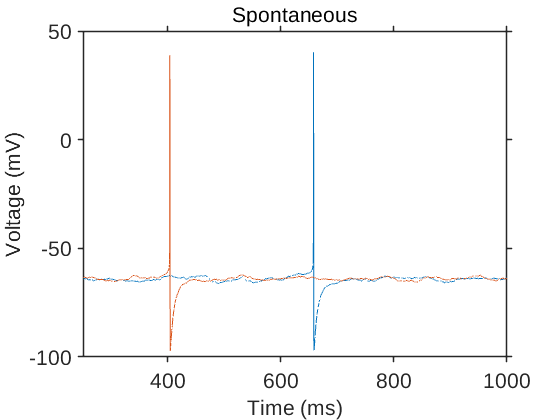

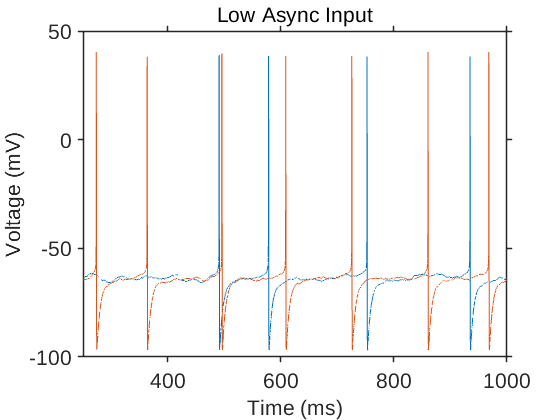

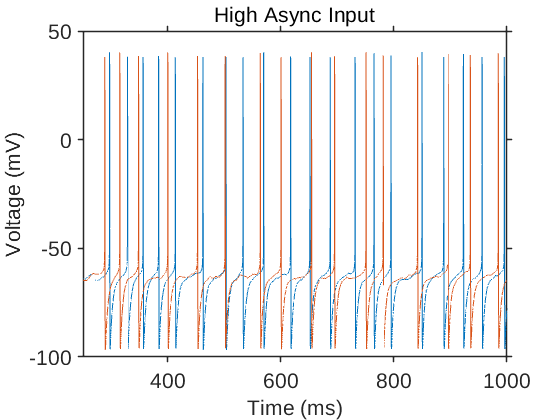


% Single-cell voltage traces (randomly picked)
fontSize = 16;
lineWidth = 1;
for iSim = 1:numel(pfcInp_DCcond)
    figure
    plot(data(iSim).time,data(iSim).D1_SPN_V(:,randi(multiplicity(1))),data(iSim).time,data(iSim).D2_SPN_V(:,randi(multiplicity(2))),'LineWidth',lineWidth)
    set(gca,'fontSize',fontSize,'LineWidth',lineWidth,'TickDir','out','Box','on');
    xlim(tl)
    xlabel('Time (ms)','fontSize',fontSize)
    ylabel('Voltage (mV)','fontSize',fontSize)
    title(pfcInp_DCcond_labels{iSim},'fontSize',fontSize,'FontWeight','Normal');

end